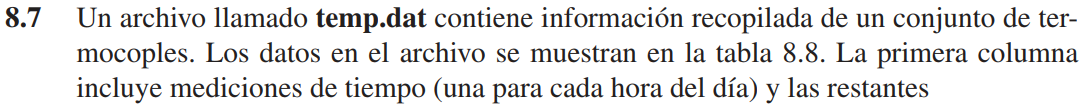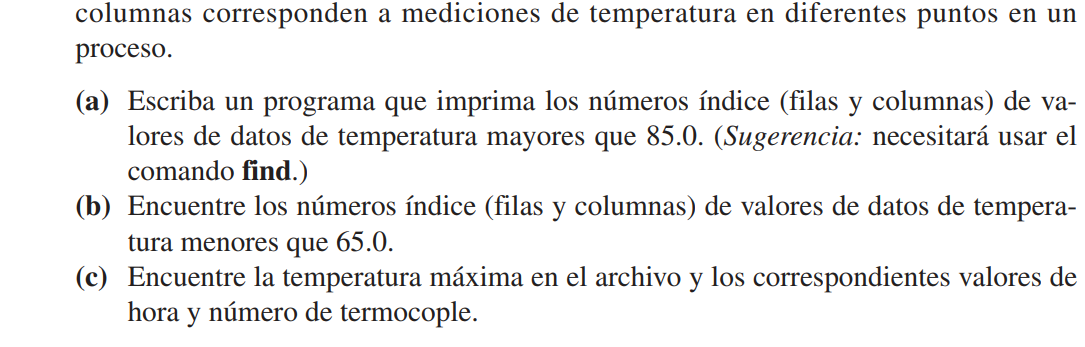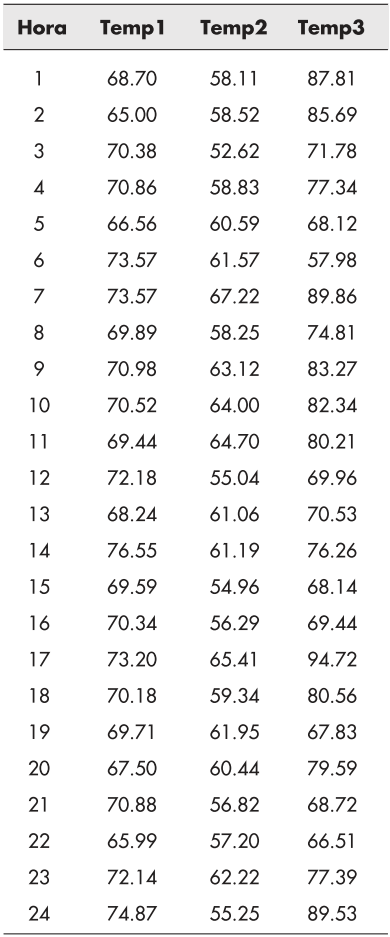

% Se define lo que se conoce.
clear

time = 1:24;
temp = [
    68.70 58.11 87.81
    65.00 58.52 85.69
    70.38 52.62 71.78
    70.86 58.83 77.34
    66.56 60.59 68.12
    73.57 61.57 57.98
    73.57 67.22 89.86
    69.89 58.25 74.81
    70.98 63.12 83.27
    70.52 64.00 82.34
    69.44 64.70 80.21
    72.18 55.04 69.96
    68.24 61.06 70.53
    76.55 61.19 76.26
    69.59 54.96 68.14
    70.34 56.29 69.44
    73.20 65.41 94.72
    70.18 59.34 80.56
    69.71 61.95 67.83
    67.50 60.44 79.59
    70.88 56.82 68.72
    65.99 57.20 66.51
    72.14 62.22 77.39
    74.87 55.25 89.53
    ];
waterLvl = [time' temp];

% Literal a, b y c.
[row_maxTempIdx, col_maxTempIdx] = find(temp>85)

[row_minTempIdx, col_minTempIdx] = find(temp<65)

maxTemp = max(max(temp))
[row_maxTemp, col_maxTemp] = find(temp == maxTemp);
timeMaxTemp = waterLvl(row_maxTemp,1);

fprintf(['La temperatura máxima es %.2f. Esta temperatura ocurre a las %d horas \n' ...
    'en el termocople %d.'], ...
    maxTemp,timeMaxTemp,col_maxTemp)

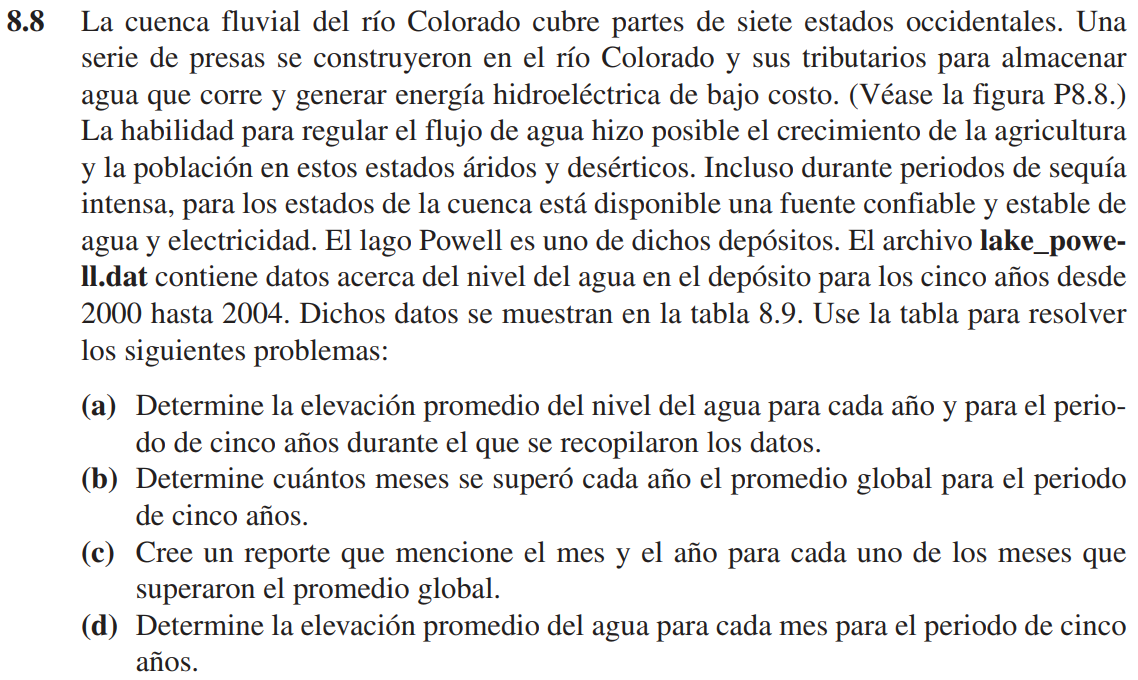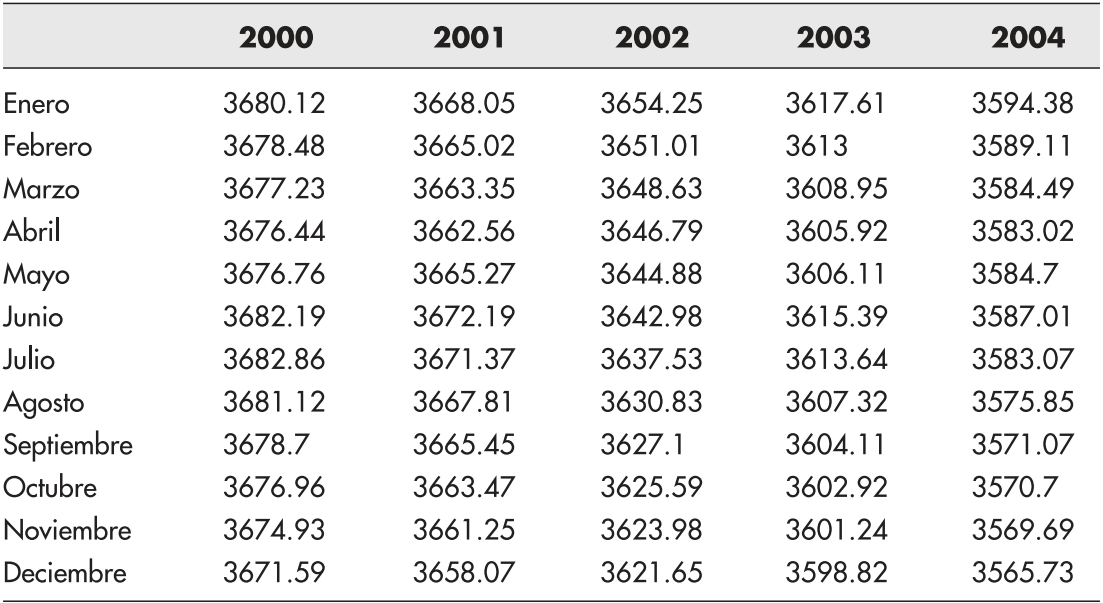

% Se define lo que se conoce.
clear

month = [
    "Enero"
    "Febrero"
    "Marzo"
    "Abril"
    "Mayo"
    "Junio"
    "Julio"
    "Agosto"
    "Septiembre"
    "Octubre"
    "Noviembre"
    "Diciembre"
    ];

% No quitar el comentario de la siguiente línea a menos que se haya leído
% el apartado final de este ejercicio.
% waterLvl = randi([3500 3700],12,5);

waterLvl = [
    3680.12 3668.05 3654.25 3617.61 3594.38
    3678.48 3665.02 3651.01 3613.00 3589.11
    3677.23 3663.35 3648.63 3608.95 3584.49
    3676.44 3662.56 3646.79 3605.92 3583.02
    3676.76 3665.27 3644.88 3606.11 3584.70
    3682.19 3672.19 3642.98 3615.39 3587.01
    3682.86 3671.37 3637.53 3613.64 3583.07
    3681.12 3667.81 3630.83 3607.32 3575.85
    3678.70 3665.45 3627.10 3604.11 3571.07
    3676.96 3663.47 3625.59 3602.92 3570.70
    3674.93 3661.25 3623.98 3601.24 3569.69
    3671.59 3658.07 3621.65 3598.82 3565.73
    ];

% Literal a.
yearlyMean = mean(waterLvl)
globalMean = mean(waterLvl(:))

% Literal b.
waterLvlExc2000 = length(find(waterLvl(:,1)>globalMean))
waterLvlExc2001 = length(find(waterLvl(:,2)>globalMean))
waterLvlExc2002 = length(find(waterLvl(:,3)>globalMean))
waterLvlExc2003 = length(find(waterLvl(:,4)>globalMean))
waterLvlExc2004 = length(find(waterLvl(:,5)>globalMean))

% Literal c.
data2000 = [month(find(waterLvl(:,1)>globalMean)) zeros(waterLvlExc2000,1)+2000]';
data2001 = [month(find(waterLvl(:,2)>globalMean)) zeros(waterLvlExc2001,1)+2001]';
data2002 = [month(find(waterLvl(:,3)>globalMean)) zeros(waterLvlExc2002,1)+2002]';
data2003 = [month(find(waterLvl(:,4)>globalMean)) zeros(waterLvlExc2003,1)+2003]';
data2004 = [month(find(waterLvl(:,5)>globalMean)) zeros(waterLvlExc2004,1)+2004]';

disp('Reporte de los meses que superaron la media global en cada año.')
fprintf('           Año                 Mes')
fprintf('%15s %18s\n',flipud(data2000))
fprintf('%15s %18s\n',flipud(data2001))
fprintf('%15s %18s\n',flipud(data2002))
fprintf('%15s %18s\n',flipud(data2003))
fprintf('%15s %18s\n',flipud(data2004))

% Literal d.
monthlyMean = mean(waterLvl,2)

**EXTRA**

Aunque no lo solicita, se mostrará por pantalla el año, el mes, el nivel de agua y la diferencia entre el nivel de agua del respectivo mes que supera la media y la media global.

**Nota:** Si se quiere probar cómo funciona el siguiente código con unos niveles de agua aleatorios y corroborar que la información del reporte sea correcta se debe ir al inicio de este ejercicio, poner como comentario los datos de nivel de agua proporcionados por el ejercicio y quitar el comentario de la línea de código que genera la nueva base de datos con números aleatorios.

Primero se generará una matriz con la información que se desplegará.

waterLvl2000 = waterLvl(find(waterLvl(:,1)>globalMean),1);
dataTotal2000 = [zeros(waterLvlExc2000,1)+2000 month(find(waterLvl(:,1)>globalMean))...
    waterLvl2000 waterLvl2000-globalMean]';

waterLvl2001 = waterLvl(find(waterLvl(:,2)>globalMean),2);
dataTotal2001 = [zeros(waterLvlExc2001,1)+2001 month(find(waterLvl(:,2)>globalMean))...
    waterLvl2001 waterLvl2001-globalMean]';

waterLvl2002 = waterLvl(find(waterLvl(:,3)>globalMean),3);
dataTotal2002 = [zeros(waterLvlExc2002,1)+2002 month(find(waterLvl(:,3)>globalMean))...
    waterLvl2002 waterLvl2002-globalMean]';

waterLvl2003 = waterLvl(find(waterLvl(:,4)>globalMean),4);
dataTotal2003 = [zeros(waterLvlExc2003,1)+2003 month(find(waterLvl(:,4)>globalMean))...
    waterLvl2003 waterLvl2003-globalMean]';

waterLvl2004 = waterLvl(find(waterLvl(:,5)>globalMean),5);
dataTotal2004 = [zeros(waterLvlExc2004,1)+2004 month(find(waterLvl(:,5)>globalMean))...
    waterLvl2004 waterLvl2004-globalMean]';

Entonces desplegamos la información por pantalla.

disp('Reporte de los meses que superaron la media global en cada año.')
fprintf('   Año         Mes         Nivel de agua       Diferencia de nivel')
fprintf('%7s %12s %16s %22s\n',dataTotal2000)
fprintf('%7s %12s %16s %22s\n',dataTotal2001)
fprintf('%7s %12s %16s %22s\n',dataTotal2002)
fprintf('%7s %12s %16s %22s\n',dataTotal2003)
fprintf('%7s %12s %16s %22s\n',dataTotal2004)